# Lerner index calculation of selected market participants

## Load marginal cost and price data

load("MCPolyfitResults.mat");
load("selDateTimePriceISONE.mat");

## Calculate Lerner index

selMCPriceTables = cell(numSelParts, 1);
quantLerner4Plots = cell(numSelParts, 1);
quadLernerModel = zeros(numSelParts, 3);
quadLernerS = cell(numSelParts, 1);
quadLernerMu = zeros(numSelParts, 2);
for n=1:size(selMCPriceTables, 1)
    selMCTable = selCleanedPartQMCTables{n};
    % Join with price table
    selMCPriceTable = outerjoin(selMCTable,selDateTimePrice,'Type','left','Keys',{'Date','Hour'},'MergeKeys',true, ...
        "LeftVariables",{'Awarded', 'MCMarket', 'MCQuadFit', 'MCCubicFit', 'Date', 'Hour'}, "RightVariables", {'averageLMP', 'affectFactor'});
    selMCPriceTable.LernerData = (selMCPriceTable.averageLMP - selMCPriceTable.MCMarket)./selMCPriceTable.averageLMP;
    % Quadratic fit of Lerner index
    [p, S, mu] = polyfit(selMCPriceTable.Awarded, selMCPriceTable.LernerData, 2);
    [y_fit, delta] = polyval(p, selMCPriceTable.Awarded, S, mu);
    selMCPriceTable.LernerQuad = y_fit;
    selMCPriceTables{n} = selMCPriceTable;
    quadLernerModel(n, :) = p;
    quadLernerS{n} = S;
    quadLernerMu(n, :) = mu;
    % Fitting data for plot
    quantity4Plot = [min(selMCPriceTable.Awarded):max(selMCPriceTable.Awarded)]';
    Lerner4Plot = polyval(p, quantity4Plot, S, mu);
    quantLerner4Plots{n} = [quantity4Plot, Lerner4Plot];
end

## Plot Lerner index

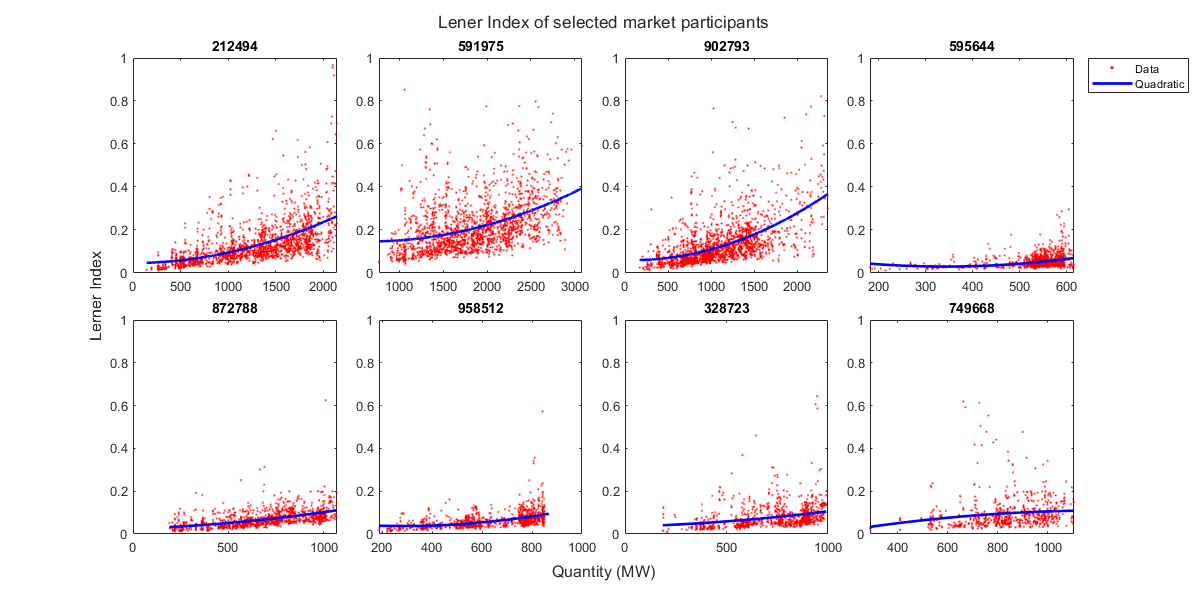

% Plot quantity vs marginal cost of selected market participants
plotColumn = 4;
t = tiledlayout(numSelParts/plotColumn, plotColumn, "TileSpacing","compact");
for n = 1:numSelParts
    nexttile;
    selMCPriceTable = selMCPriceTables{n};
    partID = selPartIDs(n);
    scatter(selMCPriceTable.Awarded, selMCPriceTable.LernerData, 10, 'r.');
    hold on;
    % Plot quadratic estimation
    quantity4Plot = quantLerner4Plots{n}(:, 1);
    Lerner4Plot = quantLerner4Plots{n}(:, 2);
    plot(quantity4Plot, Lerner4Plot, 'b-', "LineWidth", 2);
    hold off; box on;
    title(partID);
    ylim([0, 1]);
    if n==plotColumn
        legend(["Data", "Quadratic"], "Location","bestoutside");
    end
end
xlabel(t, "Quantity (MW)");
ylabel(t, "Lerner Index");
title(t, "Lener Index of selected market participants");
set(gcf, "Position", [50, 50, 1200, 600]);
saveas(gcf, "../model_output/figures/LernerQuadPolyfit.png");

## Write Lerner index results to file

save("LernerPolyfitResults.mat", "selMCPriceTables", "-mat");
save("LernerPolyfitQuad.mat", "quadLernerModel", "quadLernerS", "quadLernerMu", "-mat");